**How did you initialize the clustering process and why do you believe this is a good method of doing it?**

**Divide the oranges:**

K = 8;               % number of clusters used
L = 40;              % number of iterations
seed = 123123;            % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

kmeansexample(K,L,seed,scale_factor,image_sigma, 'orange.jpg');

Elapsed time is 78.580099 seconds.


**Divide tiger1**

K = 4;               % number of clusters used
L = 40;              % number of iterations
seed = 123123;            % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 3;   % image preblurring scale

kmeansexample(K,L,seed,scale_factor,image_sigma, 'tiger1.jpg');


**Divide tiger2**

K = 5;               % number of clusters used
L = 40;              % number of iterations
seed = 123123;            % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 3;   % image preblurring scale

kmeansexample(K,L,seed,scale_factor,image_sigma, 'tiger2.jpg');

**Divide tiger3**

K = 4;               % number of clusters used
L = 40;              % number of iterations
seed = 123123;            % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 2;   % image preblurring scale

kmeansexample(K,L,seed,scale_factor,image_sigma, 'tiger3.jpg');



**Mean shift:**

**Tiger1**

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 9.0;  % spatial bandwidth
colour_bandwidth = 5.0;   % colour bandwidth
num_iterations = 40;      % number of mean-shift iterations
image_sigma = 1.1;        % image preblurring scale

meanshiftex(scale_factor, spatial_bandwidth, colour_bandwidth, num_iterations, image_sigma, 'tiger1.jpg')

**Orange**

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 5.0;  % spatial bandwidth
colour_bandwidth = 50.0;   % colour bandwidth
num_iterations = 40;      % number of mean-shift iterations
image_sigma = 1.0;        % image preblurring scale

meanshiftex(scale_factor, spatial_bandwidth, colour_bandwidth, num_iterations, image_sigma, 'orange.jpg')

**Normalized cuts**

**Tiger2**

colour_bandwidth = 12.0; % color bandwidth
radius = 3;              % maximum neighbourhood distance
ncuts_thresh = 0.065;      % cutting threshold
min_area = 200;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 1.0;      % image downscale factor
image_sigma = 2.0;        % image preblurring scale

normcutex(colour_bandwidth, radius, ncuts_thresh, min_area, max_depth, scale_factor, image_sigma, 'tiger2.jpg');

**Orange**

colour_bandwidth = 23.0; % color bandwidth
radius = 5;              % maximum neighbourhood distance
ncuts_thresh = 0.07;      % cutting threshold
min_area = 200;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.5;      % image downscale factor
image_sigma = 2.0;        % image preblurring scale

normcutex(colour_bandwidth, radius, ncuts_thresh, min_area, max_depth, scale_factor, image_sigma, 'orange.jpg');

**White**

colour_bandwidth = 23.0; % color bandwidth
radius = 2;              % maximum neighbourhood distance
ncuts_thresh = 0.07;      % cutting threshold
min_area = 200;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 1.0;      % image downscale factor
image_sigma = 2.0;        % image preblurring scale

normcutex(colour_bandwidth, radius, ncuts_thresh, min_area, max_depth, scale_factor, image_sigma, 'white.jpg');

**Graph cut**

**Orange**

scale_factor = 0.5;          % image downscale factor
area = [60,60,450,450];%[ 80, 170, 570, 300 ];%[ 80, 110, 570, 300 ];% image region to train foreground with
K = 1;                      % number of mixture components
alpha = 10.0;                 % maximum edge cost
sigma = 55.0;                % edge cost decay factor
image = 'orange.jpg';
img = imread(image);
mask = uint8(zeros(size(img)));
mask(area(2):area(4),area(1):area(3), :) = 1; 
subplot(2,2,1);
imshow(img.*mask);

graphcutex(scale_factor, area, K, alpha, sigma, image)

**Tiger1**

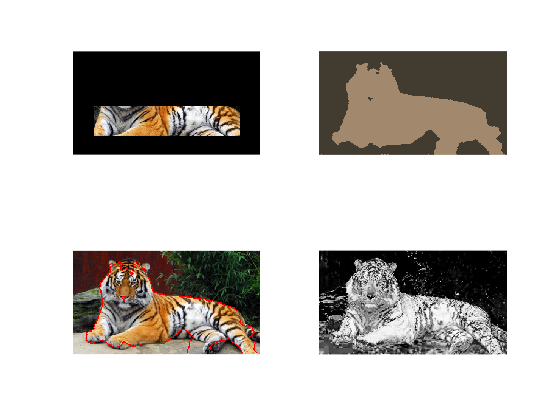

Find Gaussian mixture models...
Elapsed time is 0.359832 seconds.
Find minimum cut...
number of iterations = 100. 

Elapsed time is 0.732334 seconds.


scale_factor = 0.5;          % image downscale factor
area = [70,180,550, 280];%[80, 110, 570, 300];  %[80, 150, 570, 300];% image region to train foreground with
K = 4;                      % number of mixture components
alpha = 12.0;                 % maximum edge cost
sigma = 10.0;                % edge cost decay factor
image = 'tiger1.jpg';

img = imread(image);
mask = uint8(zeros(size(img)));
mask(area(2):area(4),area(1):area(3), :) = 1; 
subplot(2,2,1);
imshow(img.*mask);

graphcutex(scale_factor, area, K, alpha, sigma, image)

**Tiger2**

scale_factor = 0.5;          % image downscale factor
area = [150,90,420, 240];%[80, 110, 570, 300];  %[80, 150, 570, 300];% image region to train foreground with
K = 16;                      % number of mixture components
alpha = 12.0;                 % maximum edge cost
sigma = 10.0;                % edge cost decay factor
image = 'tiger2.jpg';

img = imread(image);
mask = uint8(zeros(size(img)));
mask(area(2):area(4),area(1):area(3), :) = 1; 
subplot(2,2,1);
imshow(img.*mask);

graphcutex(scale_factor, area, K, alpha, sigma, image)

**Tiger3**

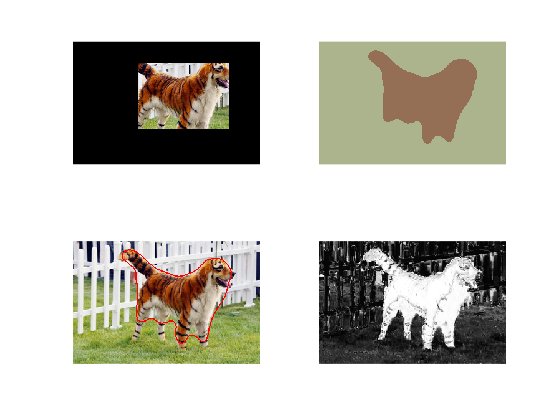

Find Gaussian mixture models...
Elapsed time is 1.980826 seconds.
Find minimum cut...
number of iterations = 100. 

Elapsed time is 2.392914 seconds.


scale_factor = 0.5;          % image downscale factor
area = [210,70,500, 280];%[80, 110, 570, 300];  %[80, 150, 570, 300];% image region to train foreground with
K = 16;                      % number of mixture components
alpha = 12.0;                 % maximum edge cost
sigma = 5.0;                % edge cost decay factor
image = 'tiger3.jpg';

img = imread(image);
mask = uint8(zeros(size(img)));
mask(area(2):area(4),area(1):area(3), :) = 1; 
subplot(2,2,1);
imshow(img.*mask);

graphcutex(scale_factor, area, K, alpha, sigma, image)